# Dot product $V_1 \text{ }\bullet V_2 \text{ }$ and Cross product $V_1 \text{ }\times \text{ }V_2$ for 2 vectors

clear
clc
rng(50, 'v5normal');


Row Vector : $V_a =\text{ }\left\lbrack \begin{array}{c}
a_1  & a_2  & a_3 
\end{array}\right\rbrack$ and $V_b =\text{ }\left\lbrack \begin{array}{c}
b_1  & b_2  & b_3 
\end{array}\right\rbrack \text{ }$

vector_a = randn(1, 3);
vector_b = randn(1, 3);



Vector dot product : $V_a \text{ }\bullet \text{ }V_b^T =\text{ }\left\lbrack \begin{array}{c}
a_1  & a_2  & a_3 
\end{array}\right\rbrack \text{ }\bullet \text{ }\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
b_3 
\end{array}\right\rbrack =\text{ }a_1 b_1 +\text{ }a_2 b_2 +\text{ }a_3 b_3$

dot_prod = dot(vector_a, vector_b)

dot_prod = -3.4826

Vector cross product : 

cross_prod = cross(vector_a, vector_b)

cross_prod =     1.2835   -1.9162   -4.5930


How to calculate the cross product of 2 vectors? The below code shows the principle :

$\left\lbrack \begin{array}{c}
V_a \\
V_b 
\end{array}\right\rbrack =\text{ }\left\lbrack \begin{array}{c}
a_1  & a_2  & a_3 \\
b_1  & b_2  & b_3 
\end{array}\right\rbrack$,   $V_a \times \text{ }V_b =\text{ }\left\lbrack \begin{array}{c}
det\left(\left\lbrack \begin{array}{c}
a_2  & a_3 \\
b_2  & b_3 
\end{array}\right\rbrack \right) & −det\left(\left\lbrack \begin{array}{c}
a_1  & a_3 \\
b_1  & b_3 
\end{array}\right\rbrack \right) & det\left(\left\lbrack \begin{array}{c}
a_1  & a_2 \\
b_1  & b_2 
\end{array}\right\rbrack \right)
\end{array}\right\rbrack$

vector_ab = [vector_a; vector_b];
det_vector_ab(1) = det(vector_ab(:, [2, 3]));
det_vector_ab(2) = -det(vector_ab(:, [1, 3]));
det_vector_ab(3) = det(vector_ab(:, [1, 2]));
det_vector_ab         % this vector is identical to the cross_prod

det_vector_ab =     1.2835   -1.9162   -4.5930


Display the 3D vector diagram for the cross product

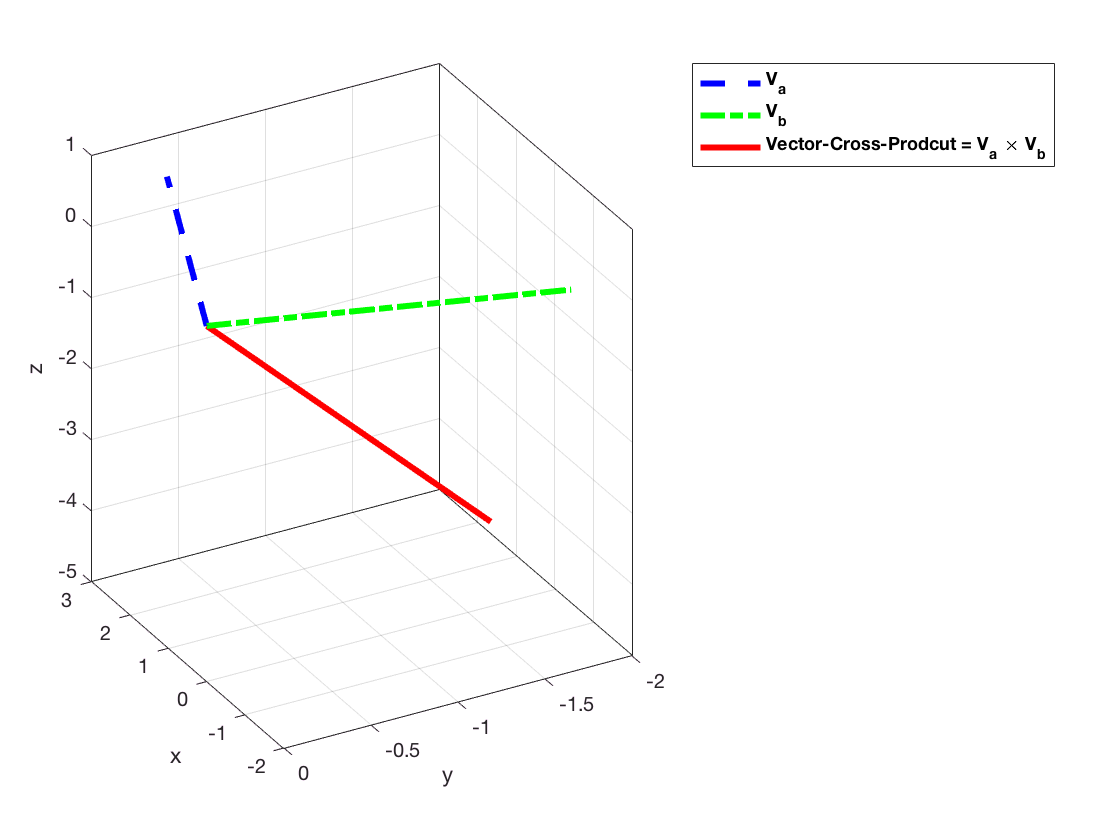

plot3([0; vector_a(1)], [0; vector_a(2)], [0; vector_a(3)], ...
'b--', 'LineWidth', 3);    % plot vector_a

hold on;

plot3([0; vector_b(1)], [0; vector_b(2)], [0; vector_b(3)], ...
'g-.', 'LineWidth', 3);    % plot vector_b

plot3([0; det_vector_ab(1)], [0; det_vector_ab(2)], [0; det_vector_ab(3)], ...
'r', 'LineWidth', 3);    % plot the cross product of vector_a and vector_b

hold off;
grid on;
box on;
xlabel('x');
ylabel('y');
zlabel('z');
view([-119, 24]);
legend('\bfV_a', '\bfV_b', '\bfVector-Cross-Prodcut = {\bfV_a} {\times} {\bfV_b}');